clear all;

# Building and Inegrator via Energy Methods, Part 2

## Let's look a little bit more at how *ode45* works:

A standard *ode45* call looks like:


$$\left\lbrack t,y\right\rbrack \;=\;\textrm{ode45}\left(\textrm{@odefun},\textrm{tspan},\textrm{y0},\textrm{options}\right)$$


Where *@odefun* is a function structured to take in the state and current time as arguments, like we discussed in Part 1. With the custom header our dynamics function will now work properly. The second argument, *tspan* defines the time range to be integrated over; our system has no time dependence so this simply defines the numer of integration steps to take. *y0*, the third argument is our system's initial state, structured as an array of the same dimensioality as the state. *options* is a struct, a special MATLAB datatype for moving nonnumeric data around; this argument can be dropped and MATLAB will istead use a default set of arguments, but proper use of this struct can let you customize many of the ways in which *ode45* works.

For output we will get back *t*, a vector whose entries correspond to every point in time at which teh function was integrated and *y*, the vector which has been integrated, such that:


$$\dot{x} =f\left(x\right)\Rightarrow y=\int f\left(x\right)\textrm{dt}$$


For our problem this looks like:


$$x=\left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 \\
\dot{\theta_1 } \\
\dot{\theta_2 } 
\end{array}\right\rbrack \Rightarrow \dot{x} =\left\lbrack \begin{array}{c}
\dot{\theta_1 } \\
\dot{\theta_2 } \\
\ddot{\theta_1 } \\
\ddot{\theta_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{\theta_1 } \\
\dot{\theta_2 } \\
g_1 \left(x\right)\\
g_2 \left(x\right)
\end{array}\right\rbrack \Rightarrow y=\int \;\dot{x} \textrm{dt}=x$$


Which is to say that the output *y* of *ode45* returns the state vector *x* at each point in time *ode45* integrates over. This is really convient for us since it makes plotting incredibly easy (we get the joint states back directly from the integrator with no extra work).

## Let's start implementing *ode45* in our code:

First, we'll set up the equations to integrate over. Note that we're integrating to find *x*, but the function we built at the end of Part 1 just returns the matrices we'd need to actually slve for the state, so we need to build another function capable of calling it and actually building the $\dot{x}$ vector for inegration. 

We'll also intrduce a term *beta* representing system damping, to give our rsults a better physical intuition. Because damping effects don't conserve energy they won't appear in our Lagangian formulation, forcing us to account for them in a different way. In this instance, becasue damping represents energy loss dependen on the joint velocities, it appears as a negative term inside the term multiplied by the inverse of *M*.

**Because of how MATLAB handles functions this is a commented out peice of code for you to look at here; the actual function definition is at the end of the file.**

%{
function dx = doublePend(t,x)
    q = x(1:2); dq = x(3:4);

    M,C,G = dynMats(t,x);

    %build our control law - we have two joints, so the control input tau
    %is a 2x1 vector, we can set which ever joint we don't want to actuate
    %to 0
    %feel free to expiriment with different contorl laws here
    tau = [...
        0;
        0];

    beta = [...
        .1, 0;
        0, .1];

    ddq = M\(tau - C*dq - beta*dq - G);

    dx = [dq; ddq];

end
%}

Now we have the function for *ode45* to integrate over, we can begin to setup the actual function call:

tspan = [0, 10]; %I can either specify a start/end time as I've done here, or use MATLAB iterator syntax a:b:c to setup a mesh to integrate over; either will work for this case
x0 = [...
    pi/2;
    pi;
    0;
    0]; %initialize the robot straight down
[t,y] = ode45(@doublePend,tspan,x0);

Let's plot a few things.

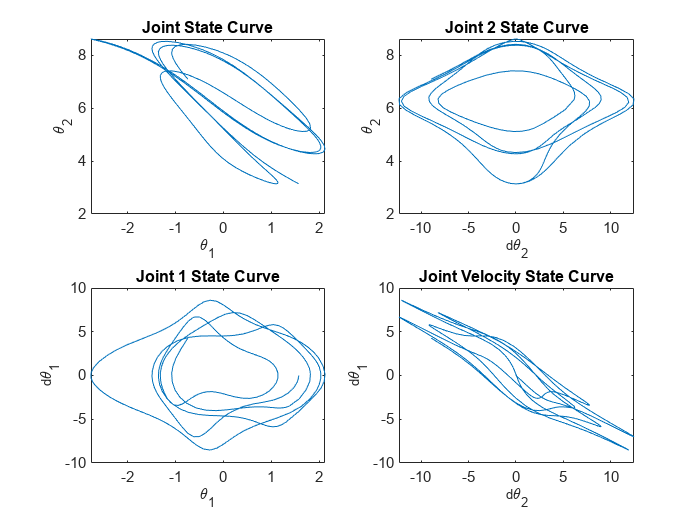

figure();
subplot(2,2,1);
plot(y(:,1),y(:,2)) %mod(y(:,1),2*pi), mod(y(:,2),2*pi));
title("Joint State Curve")
xlabel("\theta_1")
ylabel("\theta_2")

subplot(2,2,3);
plot(y(:,1),y(:,3)) %mod(y(:,1),2*pi), y(:,3));
title("Joint 1 State Curve")
xlabel("\theta_1")
ylabel("d\theta_1")

subplot(2,2,2)
plot(y(:,4), y(:,2))%mod(y(:,2),2*pi));
title("Joint 2 State Curve")
xlabel("d\theta_2")
ylabel("\theta_2")

subplot(2,2,4)
plot(y(:,4), y(:,3));
title("Joint Velocity State Curve")
xlabel("d\theta_2")
ylabel("d\theta_1")

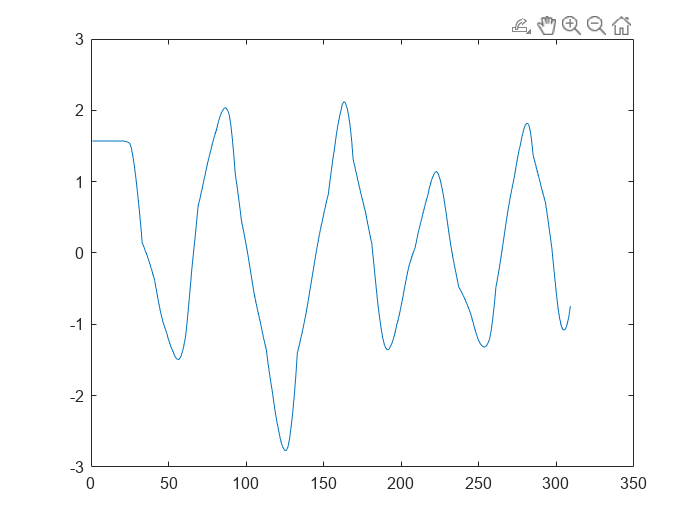


figure();
plot(y(:,1));

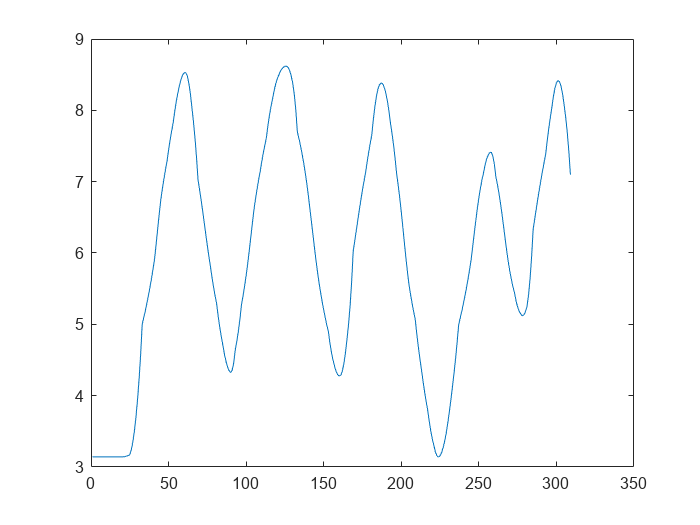

figure();
plot(y(:,2));

Let's also animate our function:

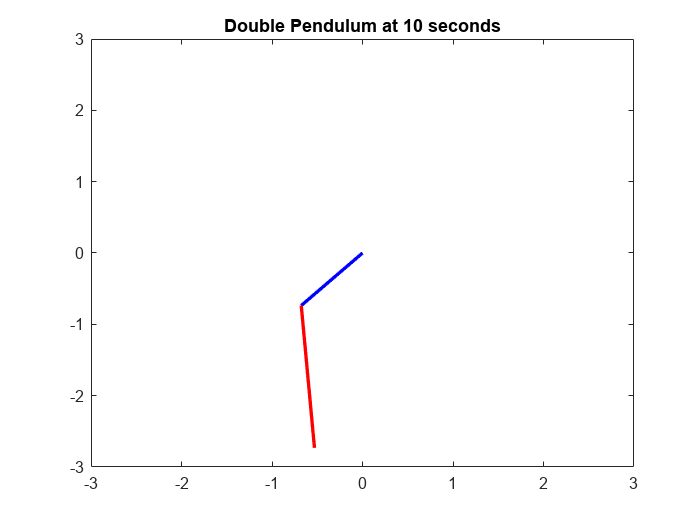

tht1 = y(:,1); tht2 = y(:,2) + tht1;
a1 = 1; a2 = 2;

figure(); 

for i = 1:max(size(y))
    p1 = [...
        a1*sin(tht1(i));
        -a1*cos(tht1(i))];

    p2 = p1 + [...
        a2*sin(tht2(i));
        -a2*cos(tht2(i))];

    plot([0, p1(1)],[0, p1(2)], 'b-','LineWidth',2); hold on;
    plot([p1(1), p2(1)], [p1(2), p2(2)], 'r-','LineWidth',2);
    xlim([-a1 - a2, a1 + a2])
    ylim([-a1 - a2, a1 + a2])
    title("Double Pendulum at " + t(i) + " seconds"); hold off; drawnow
end

## Functions

Here's the function for passing into *ode45*:

function dx = doublePend(t,x)
    q = x(1:2); dq = x(3:4);

    [M,C,G] = dynMats(t,x);

    %build our control law - we have two joints, so the control input tau
    %is a 2x1 vector, we can set which ever joint we don't want to actuate
    %to 0
    %feel free to expiriment with different control laws here
    tau = [...
        0;
        0];

    beta = 0;%[...
        %.1, 0;
       % 0, .1];

    ddq = M\(tau - C*dq - beta*dq - G);

    dx = [dq; ddq];

end